# Create and Customize 3-D Pie Charts

3-D pie charts are circular statistical graphs that are divided into wedges.

### Read Cars Data

We will use "`carbig.mat" `to demonstrate how to create and customize pie charts. The MAT-file contains various measurement data of 406 models of cars such as MPG, Horsepower, Displacement, etc. released in different countries between 1970 and 1982. 

[cylinders, cylinderCount] = readCarData();

### Basic 3D Pie Chart

View the distribution in the number of cylinders for the 406 cars and observe the proportion of each type. 

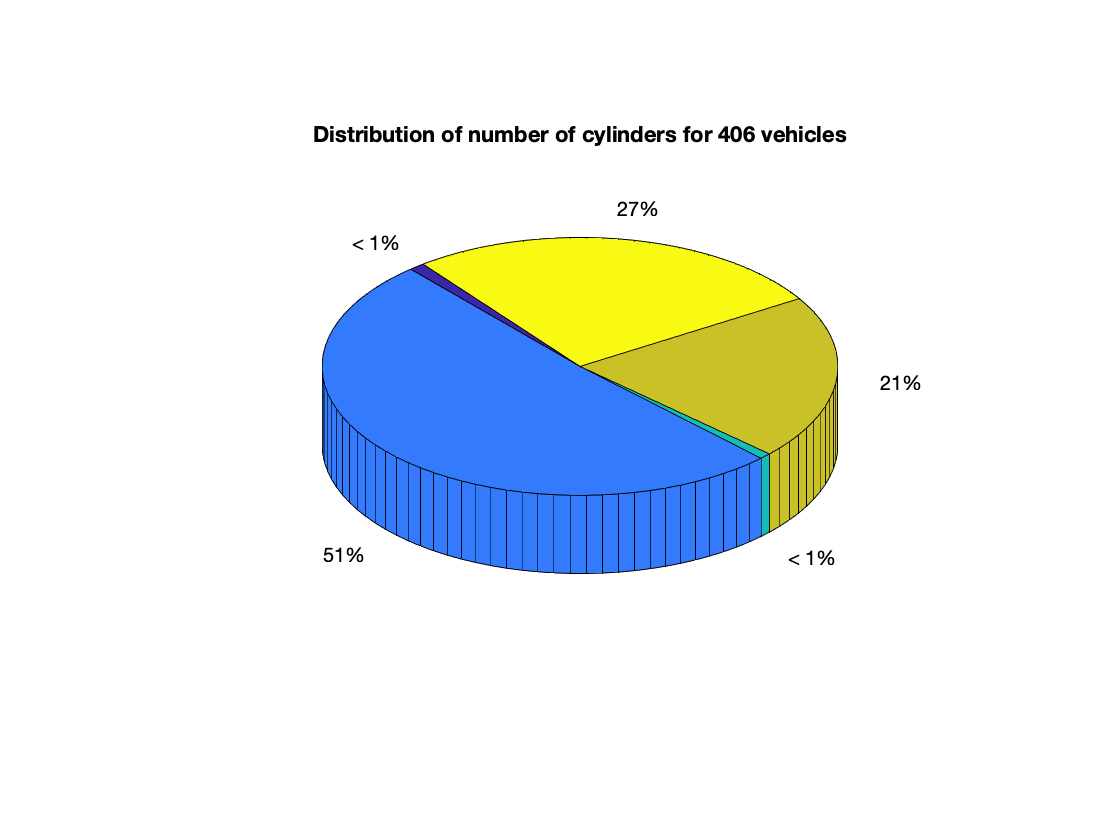

pie3(cylinderCount);
title("Distribution of number of cylinders for 406 vehicles")

## Customization

### Explode Pie Sections

To "explode" sections of the pie chart, use the second argument to `pie3`. This allows certain pie chart segments to be highlighted. Add a legend and specify its location to clearly distinguish the pie sections.

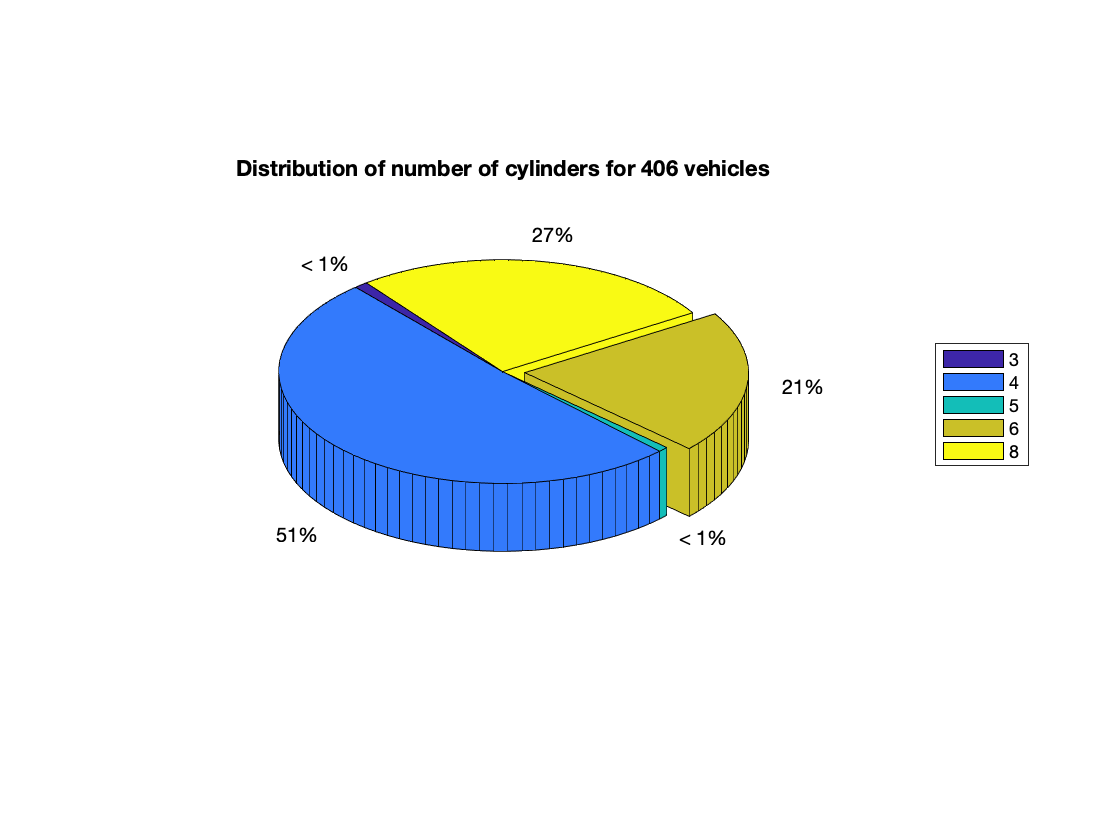

explodeInd = 4; % Specify index for exploded segment
explodeVec = zeros(1,5);
explodeVec(explodeInd) = 1;

p = pie3(cylinderCount, explodeVec);
legend(categories(cylinders),"location","eastoutside");
title("Distribution of number of cylinders for 406 vehicles")

### Customize Pie Chart Labels

The default labels include the percentage represented by each pie chart section. Pie chart labels can be cusotmized to include the number of cylinders and the percentage of the cars with that number of cylinders.

The `pie3` function call returns a handle containing 4*n objects where n is the number of segments on the pie chart. 

By accessing the Text objects through the plot handle and modifying the *String* properties for each label in a for loop using dot notation, the segment labels can be changed.

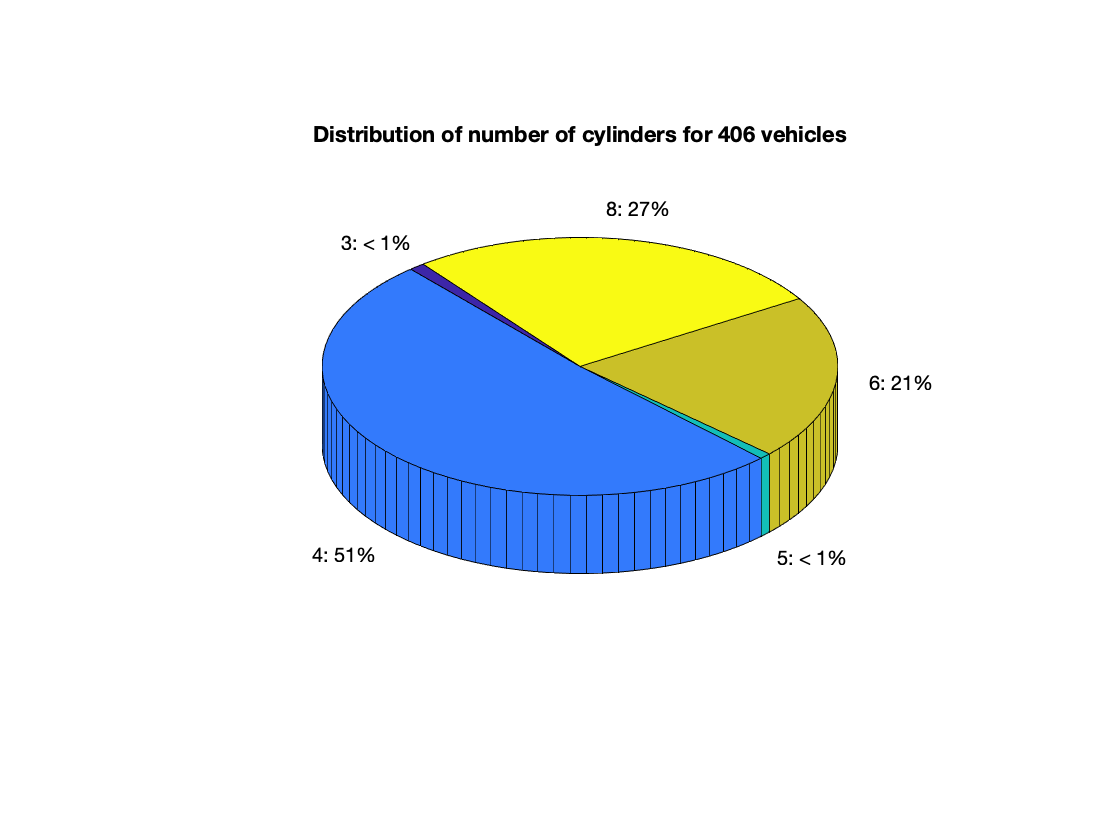

figure
p1 = pie3(cylinderCount);

pText = findobj(p1,"Type","text");   % Access Text objects
defaultLabels = get(pText,"String"); % Obtain default labels from Text objects
labels = ["3: ","4: ","5: ","6: ","8: "]; 

for i = 1:length(pText)
    pText(i).String = [labels{i} defaultLabels{i}]; % Insert desired text into label
end
title("Distribution of number of cylinders for 406 vehicles")

### Changing Chart Colormap and Lighting

There are several default colormaps specified in MATLAB, some are shown in the drop down menu. Camlight, lighting and shading can also be customized to improve plot visualization.

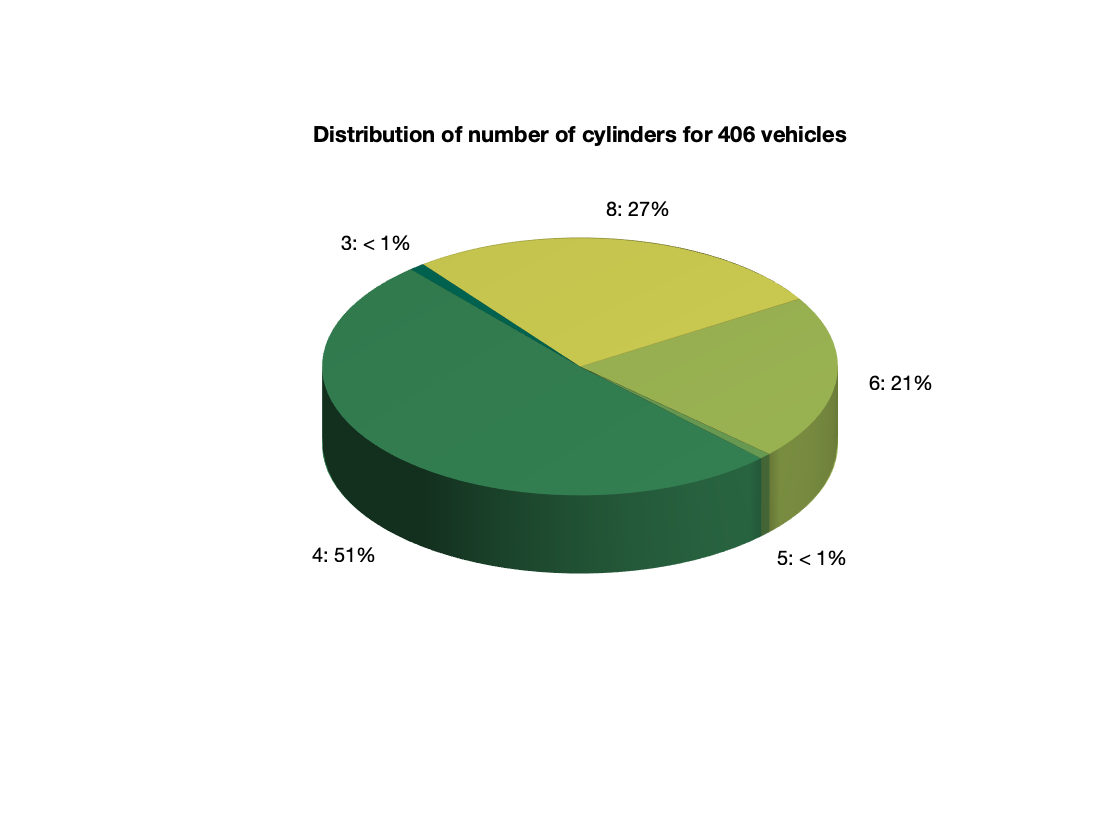

colormap("summer"); % Specify colormap
camlightType = "right";
lightingType = 'gouraud';
shadingType = "flat";

lighting(lightingType);
shading(shadingType);
camlight(camlightType);

## **Additional Information**

### **Get All Patch, Surface and Text Properties of a Pie chart**

Graphics objects in MATLAB have many properties. To see all the properties of a Patch, Surface or Text object, uncomment the following code. View or modify these properties using dot notation.

% get(p(1)) % View Patch object properties
% get(p(2)) % View Surface object properties
% get(p(4)) % View Text object properties

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[pie3](https://www.mathworks.com/help/matlab/ref/pie3.html)

### Helper Functions

This helper function reads in car data and generates variables to use in creating 3-D pie charts.

function [cylinders cylinderCount] = readCarData()
    load("carbig.mat")
    cylinders = categorical(Cylinders);
    cylinderCount = countcats(cylinders);
end

Copyright (c) 2021, The MathWorks, Inc.